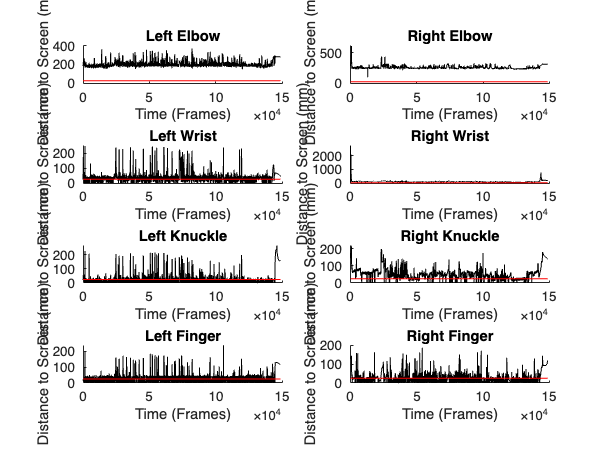

%Set desired window size, in seconds
window = 120;
fps = 30;
%Set Touch Threshold (Distance to screen in mm)
touch_threshold = 25;

%Call the function arm_data to get distances to screen
distances = arm_data(coord3D,kioskEnv,touch_threshold);

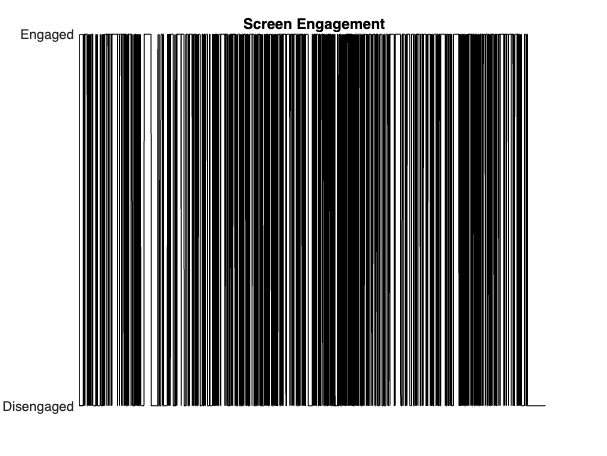

%Separate left and right distances
left_distances = sum(distances(:,3:2:end),2);
right_distances = sum(distances(:,4:2:end),2);
Lpsd = armFreqAmp(left_distances,window*fps);
Rpsd = armFreqAmp(right_distances,window*fps);

%Classify Screen Engagement
touches = screen_engagement(distances,touch_threshold);

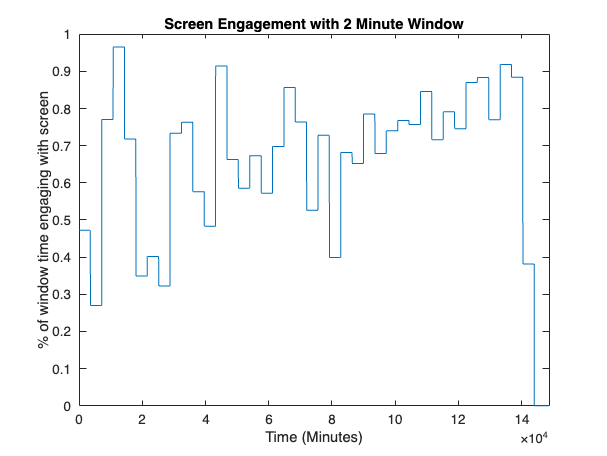

%Summarize Screen Engagement Data based on Windows
touchFreq = touchFrequency(touches,window*fps);




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function freq = touchFrequency(data,window)
    % Calculate the number of windows
    num_windows = ceil(length(data) / window);
    
    % Initialize the frequency vector
    freq = zeros(length(data), 1);
    
    % Iterate over each window
    for i = 1:num_windows
        % Define the start and end of the current window
        start_idx = (i - 1) * window + 1;
        end_idx = min(i * window, length(data));
        
        % Calculate the frequency of true values in the current window
        freq_value = window - sum(data(start_idx:end_idx));
        freq_value = (window-freq_value)./window;
        
        % Assign the frequency value to the corresponding indices in the freq vector
        freq(start_idx:end_idx) = freq_value;
    end
    figure
    time = 1:length(data);
    % time = time./30./60;
    plot(time,freq)
    title(sprintf('Screen Engagement with %d Minute Window', window./60./30));
    xlabel('Time (Minutes)');
    ylabel('% of window time engaging with screen');
    axis([0 max(time) 0 1])

end

function touches = screen_engagement(distances,threshold)
    left_touch = sum(distances(:,5:2:end)<threshold,2);
    % right_touch = sum(distances(:,6:2:end)<threshold,2);
    right_touch = distances(:,end)<threshold;
    % touch_data = (left_touch+right_touch);
    touch_data = (right_touch);
    touches = touch_data;

    figure
    time = 1:length(touches);
    % time = time./30./60;
    plot(time,touches,'k')
    set(gca,'box','off')
    set(gca,'xtick',[])
    set(gca,'xcolor',[1 1 1])
    title('Screen Engagement')
    xlabel('Time (Frames)');
    yticks([0 1]);
    yticklabels({'Disengaged', 'Engaged'});

end

function psd_plots(Lpsd,Rpsd)
    figure
    time = 1:length(Lpsd);
    time = time./30./60;
    plot(time,Lpsd)
    hold on
    plot(time,Rpsd)
    title('Power Spectral Density');
    xlabel('Time (Minutes)');
    ylabel('PSD');
    legend('Left','Right')
    % axis([0 max(time) 0 1])
    hold off

end

function psd = armFreqAmp(data,window)
    num_windows = ceil(length(data) / window);
    
    % Initialize the frequency and amplitude vectors
    freq = zeros(length(data), 1);
    amp = zeros(length(data), 1);
    psd = zeros(length(data), 1);
    
    % Sampling frequency (you may need to adjust this based on your data)
    Fs = 30; 
    
    % Iterate over each window
    for i = 1:num_windows
        % Define the start and end of the current window
        start_idx = (i - 1) * window + 1;
        end_idx = min(i * window, length(data));
        
        % Extract the current window data
        window_data = data(start_idx:end_idx);
        
        % Perform Fourier Transform on the windowed data
        Y = fft(window_data);
        N = length(window_data);
        
        Y = Y(1:floor(N/2));          % Take only the first half (positive frequencies)
        f = Fs*(0:N/2-1)/N;           % Frequency vector
        amplitude = abs(Y)/N; 

        area_under_curve = trapz(f, amplitude);
        
        % Assign the dominant frequency and amplitude to the corresponding indices
        psd(start_idx:end_idx) = area_under_curve;
    end

end

function distances = arm_data(data,kioskEnv,threshold)

    % left_elbow = data(:,10:12);
    % right_elbow = data(:,13:15);
    % left_wrist = data(:,16:18);
    % right_wrist = data(:,19:21);
    % left_knuckle = data(:,22:24);
    % right_knuckle = data(:,25:27);
    % left_finger = data(:,28:30);
    % right_finger = data(:,31:33);
    body_part = ["Nose","Left Eye","Right Eye","Left Elbow","Right Elbow","Left Wrist","Right Wrist","Left Knuckle","Right Knuckle","Left Finger","Right Finger"];
    distances = zeros(length(data),8);

    screen_plane = find_plane_from_rectangle(kioskEnv);

    for i = 1:length(data)
        for j = 12:3:width(data)
            distance = distance_point_to_plane(screen_plane, kioskEnv(1,:), data(i,j-2:j));
            distances(i,j/3-3) = smoothdata(distance,'gaussian',10*30);
        end
    end
    thres = threshold * ones(length(data),1);
    
    for i = 1:width(distances)

        subplot(4,2,i)
        hold on 
        plot(distances(:,i),'k')
        plot(thres,'r')
        set(gca,'box','off')
        title(body_part(i+3));
        xlabel('Time (Frames)');
        ylabel('Distance to Screen (mm)');
        hold off
    end
end
function [plane_normal, point_on_plane] = find_plane_from_rectangle(rect_vertices)
    % Extract the vertices of the rectangle
    v1 = rect_vertices(1, :);
    v2 = rect_vertices(2, :);
    v3 = rect_vertices(3, :);
    
    % Calculate two vectors on the plane of the rectangle
    vector1 = v2 - v1;
    vector2 = v3 - v2;
    
    % Calculate the normal vector by taking the cross product of the two vectors
    plane_normal = cross(vector1, vector2);
    
    % Normalize the normal vector
    plane_normal = plane_normal / norm(plane_normal);
    
    % A point on the plane can be any of the vertices
    point_on_plane = v1;
end

function distance = distance_point_to_plane(plane_normal, point_on_plane, point)
    % Ensure the normal vector is a unit vector
    plane_normal = plane_normal / norm(plane_normal);
    
    % Compute the vector from the point on the plane to the given point
    vector_to_point = point - point_on_plane;
    
    % Project this vector onto the plane normal vector to find the distance to the plane
    distance = abs(dot(vector_to_point, plane_normal));
end
